# Семинар 24. Постановка обратных задач, некорректность, регуляризация Тихонова

## Некоторые общие сведения и терминология 

Если принять граничные условия, свойства материалов, внутренние источники тепла и геометрию объектов за **причину** теплобмена, а тепловое состояние  объекта за **следствие**, то  найти следствие по причине - это **прямая задача**, а причину по следствию - **обратная**.

Так как процесс теплоперенса протекает во времени, нельзя поставить эксперимент по измерению непосредственно **причины, **отсюда следует "физическая" некорректность постановки обратных задач.

Постановку задач можно разделить на два класса:

- с сосредоточенными (lumped) параметрами (задачи теплообмена)

- с распределенными (disctributed) параметрами (задачи теплопроводности)

### Задачи с сосредоточенными параметрами (lumped)

Первый класс задач строится на представлении системы как совокупности отдельных объектов, которые взаимодействуют через интерфейсы, развитие этой системы во времени сводится к решению системы обыкновенных дифференциальных или дифференциально-алгебраических уравнений (matlab simulink, julia dyad). Причем, отдельные блоки внутри могут решать и уравнения в частных производных.

Например, если у нас есть $N$ изотермических элементов (то есть, каждый отдельный элемент характеризуется некоторой одной температурой), $r$ элементов при этом взаимодействуют в окружающей средой через конвекцию, а $s$  - через излучение, кроме того в каждом $n$-м элементе может выделяться тепло $Q_n$, тогда, согласно закону сохранения энергии, скорость изменения запасенного количества теплоты для каждого элемента определяется балансом поступающего к нему извне и отдаваемому им вовне тепла:

$C_n \frac {dT_n}{dt} = \Sigma_{j=1}^{N+r}\lambda_{jn}(T_j - T_n) + \Sigma_{j=1}^{N+s}K_{nj}\sigma(T_j^4 - T_n^4)A_n + Q_{n}$                                         (1)


$$n \in [1...N]$$


В уравнении выше, "причинами" являются взаимосвязи между элементами и температуры окружающего пространства, а "следствиями"  - зависимости температур элементов от времени.

$C_n$ - теплоемкость, $T_n$ - температуры элементов, $T_r$ - температуры "восстановления" окружающего пространтва, $\lambda_{jn}$ - коэффициенты теплоотдачи как взаимные между элементами, так и между элементами и окружающей средой (в общем случае каждый

элемент может быть окружен средой со своей темепратурой востановления и коэффициентом теплоотдачи), $K_{nj}$ -  коэффициенты облучения, зависящие в общем случае от угловых коэффициентов $F_{jn}$ (view factors) и излучательных способностей объектов $\epsilon_{n}$ и $\epsilon_{j}$, $A_n$ - площадь обекта, $Q_n$ - внутренние источники тепла.

Уравнение (1) может быть вкратце переписано как нелинейное обыкновенное дифференциальное уравнение:


$$\frac {d\vec{T}}{dt} = \Phi (\vec{T})$$


Здесь $\vec{T} = \matrix { T_i \cr \vdots \cr T_N}$, а $\Phi$ - некоторый нелинейный в общем случае оператор, который возвращает вектор равный по размеру вектору $\vec{T}$.

### Задачи с распределенными параметрами

Второй класс обратных задач (задачи с распределенными параметрами) построен на решении дифференциальных уравнений в частных производных (ДУЧП), второй сводится к решению обыкновенных дифференциальных уравнений. "Причиной" при решении ДУЧП служат начальные условия, граничные условия, коэффициенты уравнения,  внутренние источники. Поэтому и ОЗ для систем с распределенными разделяют на:

- **Ретроспективные** (нахождение температуры в предудущие моменты времени)

- **Граничные** (найти условия на границе)

- **Коэффициентные** (например, найти теплопроводность)

Также можно поставить задачи **геометрические**, например, в одномерной случае это может быть нахождение глубины протекания реакции, зависящей от негрва, такой, как, например термическая деструкция. И задачу на отыскание внутренних источников тепла, примером которой также может служить термодеструкция в процессе нагрева.

## Условие (математической) корректности задачи по Адамару и метод регуляризации Тихонова

#### Общая постановка задачи

## 
$$Au=f$$
 

- Решение существует для $\forall f \in F$(условие разрешимости)

- Решение единственно (условие однозначности)

- Решение непрерывно зависит от входных параметров (устойчиво), $u$ непрерывно зависит от $f$. То есть, небольшие изменения входных параметров не должны приводить к "большим" изменениям выходных.

Обратные задачи можно разделить на три больших класса:

- идентификации 

- проектирования 

- управления

Принципиальным отличием первой задачи от второй и третьей можно назвать то, что для последних, наличие множества "верных" решений (**некорректность**) это хорошо, так как годится любое решение, удовлетворяющее техническому результату  с заданной точностью. Пример - расчет многослойных структур для диэлектрики,  существует много различных структур удовлетворяющих заданной частотной зависимости. Тоже самое и с задачей управления, если решения ОЗ возвращает управляющйи сигнал, который дает нужный отклик, то нам этого достаточно. В случае идентификации множественность решений усложняет ситуацию, так, как истинная причина теплового состояния системы была одна. Например, может быть что измеренной в некоторых точках темперутре образца соотвествует множество кривых для температурной зависимости теплопроводности, тогда возникает вопрос как выбрать одну из множества (**регуляризация**).

#### Как проявляет себя некорректность при инвертировании сингулярной матрицы

Посмотрим эти критерии на примере простой обратной задачи - обращения линейного оператора:

$A\vec{b}=\vec{y}$                                                                                                            (2)

Если матрица $A$ квадратная, то в случае, если она несингулялрна она удовлетворяет всем условиям корреткности , если же $A$ сингулярна (ранг матрицы меньше размерности пространства ее столбцов, то есть, ее нуль-пространство является нетривиальным), то задача некорректна.  

Причем, если $\vec{y} \in \mathbb{N}(A^T)$ (принадлежит нуль-пространству матрицы $A^T$), то задача решения не имеет (то есть не корректна по первому критерию), а если $\vec{y}\in \mathbb{C}(A)$ (лежит в пространстве столбцов, то задача имеет бесконечно много решений), то есть, такого рода задача не удовлетворяет второму критерию. 

Для неквадратной матрицы с линейно независимыми столбцами ситуация аналогична, задача имеет решение, только если вектор $\vec{y} \in \mathbb{C}(A)$.

Таким образом если задача (2) сформулирована в общем виде, без ограничений на вектор $\vec{y}$ и матрицу $A$, такая постановка задачи будет некорректной.

#### **Некорректность в задаче линейной регрессии: сингулярная матрица предикторов**

До этого мы, решая задачу линейной регрессии, всегда оговаривались, что матрица предикторов должна быть несингулярной. Теперь будем пытаться понять как решать задачи с сингулярной матрицей.

Посмотрим на задачу линейной регрессии :

$argmin(||A\vec{b}-\vec{y}||_2^2)$                                                                        (3)

Обычно матрица $A$ имеет больше строк, чем столбцов.

 Как известно, решение этой задачи для матриц полного ранга дается  $\vec{b}=A^{\dagger}\vec{y} = (A^TA)^{-1}A^T\vec{y}$,  вектор ошибки $\vec{e}= \hat y - \vec{y} = A\vec{b} - \vec{y} $  , причем $\vec{e} \in \mathbb{N}(A^T)$ - ошибка лежит в нуль-пространстве строк матрицы $A$.

 $A^{\dagger}$ - псевдообратная матрица.

В этом случае задача будет иметь единственное решение и будет корректной. Если же ранг матрицы$A$ меньше числа ее столбцов, матрица $A^TA$ будет необратимой и задача будет некорректной по Адамару, так как имеет бесконечно много решений. 

A = [1 2 3;...
    1 2 -3;...
    2 4 0] % матрица с двумя зависимыми столбцами

A =      1     2     3
     1     2    -3
     2     4     0


y = [3;3;3] 

y =      3
     3
     3


A\y % левостороннее деление решает задачу методом QR - факторизации

ans =       -Inf
       Inf
    0.5000


Теперь:

$A^{\dagger} \neq (A^TA)^{-1}A^T$ , так как $(A^TA)^{-1}$ - сингулярна, а на ноль делить нельзя.

Псевдообратная матрица (матрица Мура-Пенроуза) в случая сингулярной матрицы $А$ все равно существует.  

Псевдообратная матрица для матриц неполного ранга рассчитывается через SVD разложение:

$A = U\Sigma V^T$, а для обратной матрицы $(A^T A)^{-1}A^T=(V\Sigma U^T U \Sigma V^T)^{-1}V \Sigma U^T = V \Sigma ^{-2} V^T (V \Sigma U^T) = V \Sigma ^{-2} \Sigma U^T $.

Таким образом, если матрица несингулярная то у нее нет нулевых сингулярных значений и псевдообратная матрица будет просто $A^{\dagger} =V \Sigma ^{-1}  U^T $.

Однако, сингулярное разложение матрицы неполного ранга  будет иметь среди сингулярных значений ноль. Поэтому при расчете $A^{\dagger}$ выкидывают все сингулярные значения равные нулю и соотвествующие им левые и правые сингулярные вектора:

$A^{\dagger} = V\Sigma ^{\dagger} U^T$ (для полноранговой матрицы $\Sigma ^{\dagger} = \Sigma ^{-1}$, а $A^{\dagger} = (A^T A)^{-1}A^T$)

$\Sigma ^{\dagger} = [\matrix{\frac{1}{\sigma_1}  &&&&0\cr
&\ddots \cr
& &\frac{1} {\sigma_i} &  \cr
&&&\ddots \cr
0&&&&0  &  \cr
}]$ (нули для всех $\sigma_n =0$)

[u,s,v] = svd(A) % сингулярное разложение исходной матрицы 

u =    -0.4082    0.7071   -0.5774
   -0.4082   -0.7071   -0.5774
   -0.8165   -0.0000    0.5774


s =     5.4772         0         0
         0    4.2426         0
         0         0    0.0000


v =    -0.4472   -0.0000    0.8944
   -0.8944   -0.0000   -0.4472
   -0.0000    1.0000    0.0000


A = u*s*v' 

A =     1.0000    2.0000    3.0000
    1.0000    2.0000   -3.0000
    2.0000    4.0000    0.0000


Sigma_dagger = inv(s(1:2,1:2))

Sigma_dagger =     0.1826         0
         0    0.2357


A_dagger_manual  = v(:,1:2)*Sigma_dagger*u(:,1:2)'

A_dagger_manual =     0.0333    0.0333    0.0667
    0.0667    0.0667    0.1333
    0.1667   -0.1667   -0.0000


A_dagger = pinv(A) 

A_dagger =     0.0333    0.0333    0.0667
    0.0667    0.0667    0.1333
    0.1667   -0.1667   -0.0000


b_pseudoinverse = pinv(A)*y % псевдообратная матрица находится при помощи SVD разложения

b_pseudoinverse =     0.4000
    0.8000
   -0.0000


Так как число решений для матрицы неполного ранга бесконечно, решение при помощи псевдообратной матрицы $A^{\dagger}\vec{y}$ для этого случая возвращает значение $\vec{b}$, которое имеет минимальную норму среди прочих.

#### **Как проявляет себя некорректность при исопользовании итерационных методов оптимизации**

Если же решать эту задачу итерационным методом оптимизации, то методы нулевого  (например Нелдера-Мида) и первого порядка (например, градиентного спуска) будут давать различные решения для различных стартовых условий ( у алгоритма нет признака, по которому он мог бы выбрать из бесконечного множества решений один локальный минимум), а метод второго порядка (например метод Ньютона) будет выдавать ошибку, так как матрица Гесса ($H=A^TA$) данном случае необратима (а шаг алгоритма по Ньютону это, как известно, $\vec{p}=-H^{-1}\nabla f$).

Для примера ниже решается задача минимизации для случайного стартового вектора:

f = @(b)(A*b - y)'*(A*b - y);% функция невязки
fminsearch(f,rand(3,1)) % случайное положение, метод Нелдера-Мида

ans =     1.7716
    0.1142
   -0.0000


Алгоритм сходится к разным значениям вследствии некорректности.

## Регуляризация Тихонова*

#### РТ для задачи линейной регресии

Сделать задачу с сингулярной матрицей корректной может помочь регуляризация Тихонова (ridge regression), в простейшем виде регуляризация может иметь только один параметр $\alpha
$ :

$min(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - формулировка исходной задачи в терминах наименьших квадратов с добавленным регуляризующим членом. 

Регуляризация  позволяет из бесконечого множества решений выбрать то, которое удовлетворят дополнительному ограничению на множество параметров оптимизации (в данном случае это ограничение на длину вектора $\vec{b}$). Раньше мы видели как ограничение на параметры оптимизации также приводит к регляризации.

Аналитическое решение регуляризационной задачи дается выражением:


$$$ \vec{b} = (A^TA + \alpha I)^{-1}A^T$$


В примере ниже решается задача линейной регрессии методом оптимизации, некорректность задача обсулавливает ее нейстойчивость по отношению к стартовому вектору (решение с которого стартует итерационный метод оптимизации)


A = [1 2 3;1 2 -3;2 4 0] % матрица с двумя зависимыми столбцами

A =      1     2     3
     1     2    -3
     2     4     0


y = [3;3;3] 

y =      3
     3
     3


alfa = -0.3 % если задать фиксированное значенеи параметра alfa, то решение будет при

alfa = -0.3000


f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)

f = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+alfa*b'*b)


b_tikhonov = fminsearch(f,rand(3,1)) % случайное положение 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -9578232076354654643454344375074588374687634366191170059756020064075477956891904584812268093440.000000 



b_tikhonov = 1.0e+47 *

    2.1783
   -0.9265
   -0.0706


% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует
b_pseudoinverse = pinv(A)*y

b_pseudoinverse =     0.4000
    0.8000
   -0.0000


Важный момент тут еще в том, что "верное" решение теперь зависит от параметра $\alpha$!

То есть, с точки зрения статистикого подхода, оценка становится смещенной! ( в отличие от оценки $A^{\dagger}\vec{y}$, которая, если существует является несмещенной.

clearvars
noise = 0.5

noise = 0.5000

a = 0.01:0.01:30;
A = [1 2 ;1 2;2 4] % матрица с двумя зависимыми столбцами

A =      1     2
     1     2
     2     4


y = [3;3;3] + noise*rand(3,1)

y =     3.0759
    3.0805
    3.1040


b_v = zeros(length(a),2);
counter=0

counter = 0

b_start = [2;1]

b_start =      2
     1


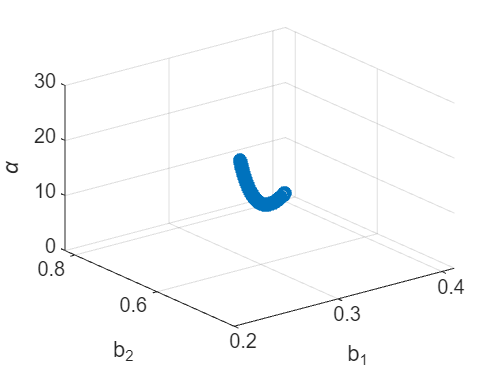

b_pseudoinverse = pinv(A)*y;
for ai = a
    f_i = @(b)((A*b - y)'*(A*b - y) + ai*b'*b);
    counter = counter + 1;
    b_v(counter,:) = fminsearch(f_i,b_start); % случайное положение 
end
% зависимость решения от параметра регуляризации
scatter3(b_v(:,1),b_v(:,2),a)
zlabel("\alpha");ylabel("b_2");xlabel("b_1")

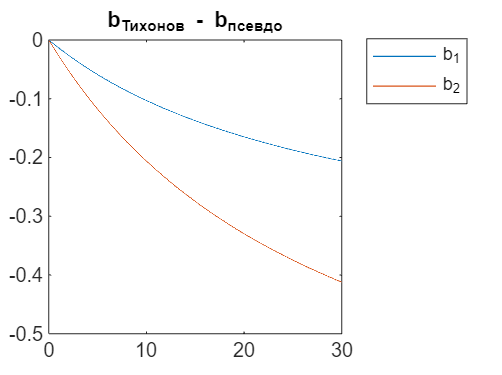

plot(a,(b_v' - b_pseudoinverse));legend(["b_1" , "b_2"])
title("b_{Тихонов} - b_{псевдо}")

Видно, что решение методом регуляризации Тихонова стремится к решению при помощи псевдообратной матрицы при параметре регулризации стремящимся к нулю. Это легко показать аналитически:


$$$ \vec{b} = (A^TA + \alpha I)^{-1}A^T$$


Видно, что она добавляет к изначально близкой к сингуярной матрице $A^TA $ диагональную матрицу, тем самым "усиливая" диагональ, то есть, линейную независимость ее столбцов:


$$A^TA + \alpha I = V \Sigma U^T U \Sigma V^T + \alpha I = V \Sigma^2 V^T + \alpha V I V^T = V (\Sigma^2 + \alpha I) V^T =  
V[\matrix{\sigma_1^2 + \alpha  &&&&0\cr
&\ddots \cr
& & \sigma_i^2  + \alpha &  \cr
&&&\ddots \cr
0&&&&\sigma_n^2  + \alpha  &  \cr
}]V^T $$



$$(A^TA + \alpha I)^{-1} A^T= V (
[\matrix{\frac{\sigma_1}{\sigma_1^2 + \alpha}  &&&&0\cr
&\ddots \cr
& &\frac{\sigma_i} {\sigma_i^2  + \alpha} &  \cr
&&&\ddots \cr
0&&&&\frac{\sigma_n}{\sigma_n^2  + \alpha}  &  \cr
}] U^ T = V \mathrm{diag}(\frac{\sigma_i}{\sigma_i^2 + \alpha})U^T$$


Из этого выражения видно, что элементы, стоящие на диагонали:

$\lim_{\sigma \to 0} \frac{\sigma}{\sigma^2  + \alpha} = 0$ - то есть, для очень малых значений близких к нулю регуляризованное решение тоже работает

$\lim_{\sigma \to \infty} \frac{\sigma}{\sigma^2  + \alpha} = \frac{1/\sigma}{1  + \alpha /\sigma^2} = 0$ - то есть, и для очень больших значений  регулризованное решение стремится к нулю

$\lim_{\alpha\to 0} \frac{\sigma}{\sigma^2  + \alpha}  = \frac{1}{\sigma}$ - то есть регуляризованное решение стремится к решению через псевдообратную матрицу

#### **Вариация оценки вектора параметров без регуляризации**

Если посмотреть на задачу метода наименьших квадратов с точки зрения статистики: 


$$\vec{y}=A \vec{\beta} + \vec{\epsilon}$$


$\vec{y}$ - это вектор результатов измерений, который предполагается линейной комбинацией столбцов матрицы $A$.

 $\vec{\beta}$ - это истинные значения параметров

$\vec{\epsilon}$ - случаный вектор ошибки, такой, что

$\mathrm{Cov}(\vec{\epsilon})=I\zeta^2$  - ошибка экспериментальных данных (она может быть известна), также ошибка отдельных измерений некоррелирована - матрица ковариации диагональна.

 $\mathbb{E}(\vec{\epsilon})=0$ - ошибка несмещена 

Как было показано в семинаре по регрессии (#10) решение

$\vec{b}=  (A^TA)^{-1}A^T\vec{y}$ дает несмещенную оценку $\vec{\beta}$, такую что:

$\mathbb{E}(\vec{b}) = \vec{\beta}$ - несмещенность оценки

$\mathrm{Cov}(\vec{b})= \mathbb{E}((\vec{b} - \vec{\beta})(\vec{b} - \vec{\beta})^T) = (A^TA)^{-1}\zeta^2$ - матрица ковариации

$\mathrm{Var}(\vec{b}) = \mathrm{diag}((A^TA)^{-1}\zeta^2)$ - вектор вариации

Суммарное квадратичное отклонение (самма всех компонент вектора вариации):

  
$$\zeta^2tr( (A^TA)^{-1}) =\zeta^2 tr( V \Sigma ^{-2} V^T)=\zeta^2\sum_i \frac{1}{\sigma_i^2}$$
   

(это справедливо, так как след матрицы равен сумме ее собственных значений)

Отсюда видно, что если матрица $A^TA $ близка к сингулярной, то, так как ее собственные значения при этом стремятся к нулю,  вариация "взрывается" показывает бесконечное отклонение параметров от истинного значения, неоднозначность в решения приводит к бесконечно большой вариации!

#### **Вариация оценки параметров с регуляризацией Тихонова**

Матрица ковариации для регуляризованного решения имеет вид: 


$$\[
\mathrm{Cov}(\vec{b}) = \zeta^2 \left( A^T A + \alpha I \right)^{-1} A^T A \left( A^T A + \alpha I \right)^{-1} =   \zeta^2 V \, \mathrm{diag}\left(\frac{\sigma_i^2}{(\sigma_i^2 + \alpha)^2}\right) V^T.
\]$$


Тут видно, что $\lim_{\sigma \to \infty} \frac{\sigma^2}{(\sigma^2  + \alpha)^2} =\lim_{\sigma \to \infty} \frac{\sigma^{-2}}{(1  + \alpha/\sigma^2)^2} =0$ , то есть, для регуляризованного решения, вариация не "взрывается" при приближении матрицы к сингулярности, а стремится к нулю.


$$\lim_{\sigma \to 0} \frac{\sigma^2}{(\sigma^2  + \alpha)^2} =0$$
 

#### Принцип Морозова для выбора регуляризационного множителя 

Возникает вопрос как выбрать регуляризующий множитель?

Если речь идет о регуляризаци регрессионной задачи экспериментальных данных, которые были получены с некоторой погрешностью, которая может быть известна. Можно воспользоваться принципом Морозова, который гласит (в тривиальной интерпретации):

Параметр регуляризации $\alpha$ надо выбирать так, чтобы среднеквадратичная ошибка регрессии была равна дисперсии ошибки  $\vec{y}$ .

$A\vec{\beta} = \vec{y} + \vec{e}$, здесь $\vec{e}$ - случайный вектор ошибки.


$$N\zeta^2=\vec{e}^t\vec{e}$$


$||A\vec{b}_\lambda - \vec{y}||_2^2 =\tau\zeta^2 N$, где

$\vec{b}_{\lambda} = argmin(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - решение задачи регрессии

$\tau$ - некоторый множитель близкий к единице.

Таким образом, параметр регуляризации контролирует баланс между стабильностью и точностью.

#### Регуляризация при близкой к сингулярной матрице предикторов

Если $A$ - несингулярна (ранг матрицы равен размерности пространства ее столбцов и строк, то есть, все ее столбцы / строки линейно независимы) то решение данной задачи существует и единственно, правда не всегда численно устойчиво.

$cond(A)= \frac {||A||}{||A^{-1}||}$ - число обсуловленности матрицы (conditional number)  - для l2 нормы это отношение максимального сингулярного значения к минимальному, чем оно больше, тем менее стабильным будет алгоритм обращения данной матрицы

$H_{ij} = \frac {1} {i+j-1}$ - матрица Гильберта пример матрицы у которой очень быстро растет .

sym(hilb(5))

$$ans = \left(\begin{array}{ccccc} 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7}\\ \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8}\\ \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9} \end{array}\right)$$

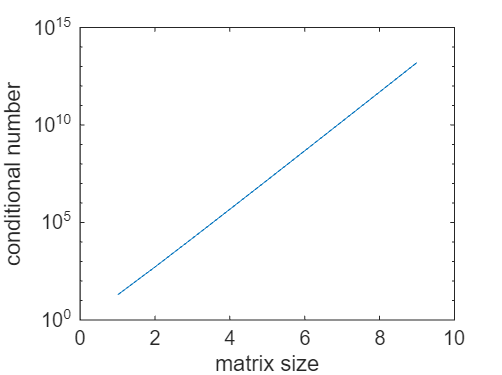


p = 2:10;
c_n = zeros(length(p),1);
for i = 1:length(p)
    p_i = p(i);
    c_n(i) = cond(hilb(p_i));% функция cond считает condition number
end
semilogy(c_n)
xlabel("matrix size");ylabel("conditional number")

Поэтому для достаточно больших размеров матрицы, решение будет неустойчиво, то есть небольшие изменения правой части будут приводить к значительным изменениям решения.

Тут опять может помочь регуляризация Тихонова.

A = hilb(8)

A =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250
    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667


y = ones(8,1);
alfa = 0.2

alfa = 0.2000

f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)

f = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+alfa*b'*b)


b_optimization = fminsearch(f,rand(8,1)) % случайное положение 

b_optimization =     0.0906
    0.7221
    0.8140
    0.8029
    0.7649
    0.7209
    0.6775
    0.6371


% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует
norm(b_optimization)

ans = 1.9511

При этом, для матрицы, близкой к сингулярной, но не сингулярной, песвдообратная матрица не очень полезна

b_pinv = pinv(A)*y

b_pinv = 1.0e+05 *

   -0.0001
    0.0050
   -0.0756
    0.4620
   -1.3860
    2.1622
   -1.6817
    0.5148


norm(b_pinv)

ans = 3.1477e+05

Можно понять почему так происходит, если посмотреть на решение задачи регуляризации Тихонова:


$$(A^TA + \alpha I)^{-1} A^T= V \mathrm{diag}(\frac{\sigma_i}{\sigma_i^2 + \alpha})U^T$$


Если построить функцию $f(\sigma)=\frac {\sigma}{\sigma^2 + \alpha}$:

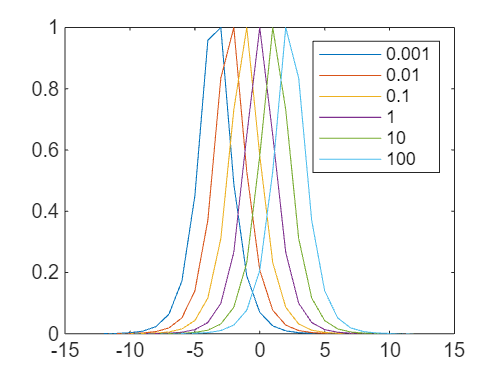

f = @(s,a) s./(a + s.^2);
x = -12:1:12;
ai = [1e-3,0.01,0.1,1,10,100];
plot(x,f(exp(x),ai(1))/max(f(exp(x),ai(1))));
hold on
for ath = ai(2:end)
    plot(x,f(exp(x),ath)/max(f(exp(x),ath)));
end
hold off
legend(string(ai))

По сути регуляризация работает как фильтр для спектра матрицы $A^TA$ отсекая и очень большие и очень маленькие значения сингулярных векторов.

### Задача с регуляризацией как задача с ограничениям

Можно посмотреть на задачу с регуляризацией, как на задачу с ограничениями:

Если исходная задача сформулирована так:


$$argmin(||A\vec{b}-\vec{y}||_2^2)$$
       

То регуляризацию можно рассматривать как дополнительное ограничение на длину вектора параметров оптимизации:


$$\vec{b}^T\vec{b} = 0$$


При строгом выполнении ограничений задача становится тривиальной, однако мы можем добавить ограничение в функцию невязки с некоторым весом (этот подход называется метод множителей Лагранжа и он часто используется для задач оптимизации с ограничениями).


$$argmin(||A\vec{b}-\vec{y}||_2^2 + \lambda\vec{b}^T\vec{b})$$
       

Собственно мы видим, что по сути это таже самая задача с регуляризацией.

### Обобщенная формулировка метода регуляризации

Везде до этого мы везде предполагали, что регуляризующий параметр только один, но везде в формулы он входит как $\alpha I$, поэтому мы могли бы легко использовать для регуляризации любую диагональную матрицу с положительными элементами на диагонали, мало того для регулризации в действительности может исоплзоваться любая положительно-определенная матрица.

 Поэтому в общем виде метод регуляризации может быть сформулирован для линейной регрессии следующим образом:


$$\vec{b}_{reg} = argmin((A\vec{b}-\vec{y})^T (A\vec{b}-\vec{y})+ \vec{b}^T\Gamma^T\Gamma\vec{b})$$


Данная форма гарантирует положительную определенность регуляризующей матрицы, так как $\Gamma^T\Gamma$ - всегда положительно определенная (это может быть разложение Холецкого)

Решение этой задачи дается выражением:


$$$ \vec{b}_{reg} = (A^TA +\Gamma^T\Gamma)^{-1}A^T\vec{y}$$


В большинстве выражений (за исключением тех , где используется сингулярное разложение) можно просто заменить $\alpha I$ на $\Gamma^T\Gamma$, например, выражение для матрицы ковариации будет:


$$\mathrm{Cov}(\vec{b_{reg}})= \zeta^2 \left( A^T A +\Gamma^T\Gamma)^{-1} A^T A \left( A^T A + \Gamma^T\Gamma)^{-1}$$


Также  бывает, что экспериментально определенная матрица ковариации используется в качестве регуляризующей матрицы $\Gamma^T\Gamma = C_{ex}^{-1}$, этот подход применяется в байесовской оптимизации.

Также в качестве регуляризующей матрицы может использоваться, например матрица конечно разностной схемы:


$$\Gamma = \matrix{
-1 & 1 & 0 & \cdots & 0 & 0  \cr
0 & -1 & 1 & \cdots & 0 & 0\cr
\vdots & & \ddots & \ddots & \vdots & 0\cr
0 & \cdots & 0 & -1 & 1 & 0\cr
0 & \cdots & \cdots & 0 & -1 & 1
}$$


Данная матрица заменяет вектор параметров оптимизации вектором их разницы.


$$\Gamma\vec{b} = \matrix { b_2  -  b_1 \cr \vdots \cr  b_n -b_{n-1}}$$



$$ \vec{b}^T  \Gamma^T\Gamma\vec{b}  = \sum_i (b_i - b_{i-1})^2$$


То есть, регуляризация подобного рода дополнительно минимизирует разницу между соседними параметрами оптимизации.

Интересно может быть использование подобного рода регуляризующий матрицы для случая когда $\vec{b}$ это коэффициенты аппроксимации полиномами Бернштейна (или сплайнов). Как обсуждалось на предыдущем семинаре, значения коэффициентов этих полиномов стремятся к значениям самой функции. Поэтому когда мы регуляризуем разницу между коэффициентами при помощи конечно-разностной матрицы, мы фактически накладываем ограничение "малого роста" на саму функцию, таким образом кривая зависимости должна стать более плавной.

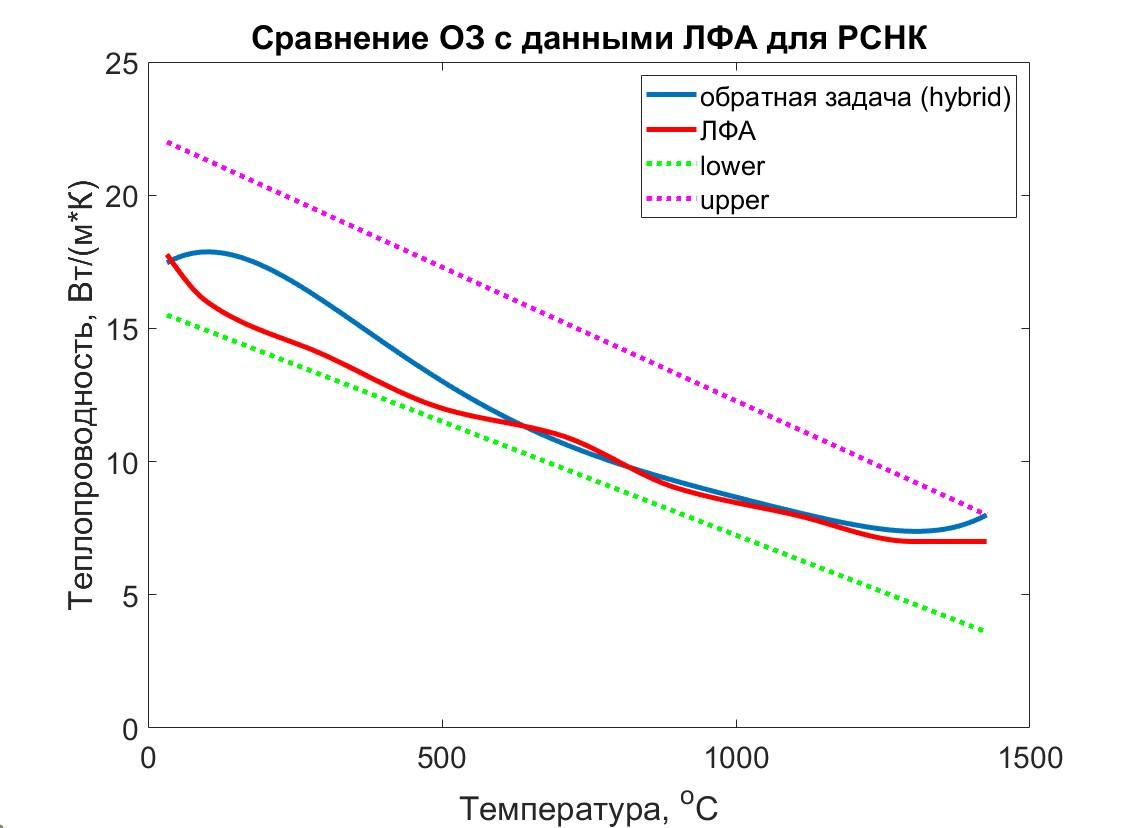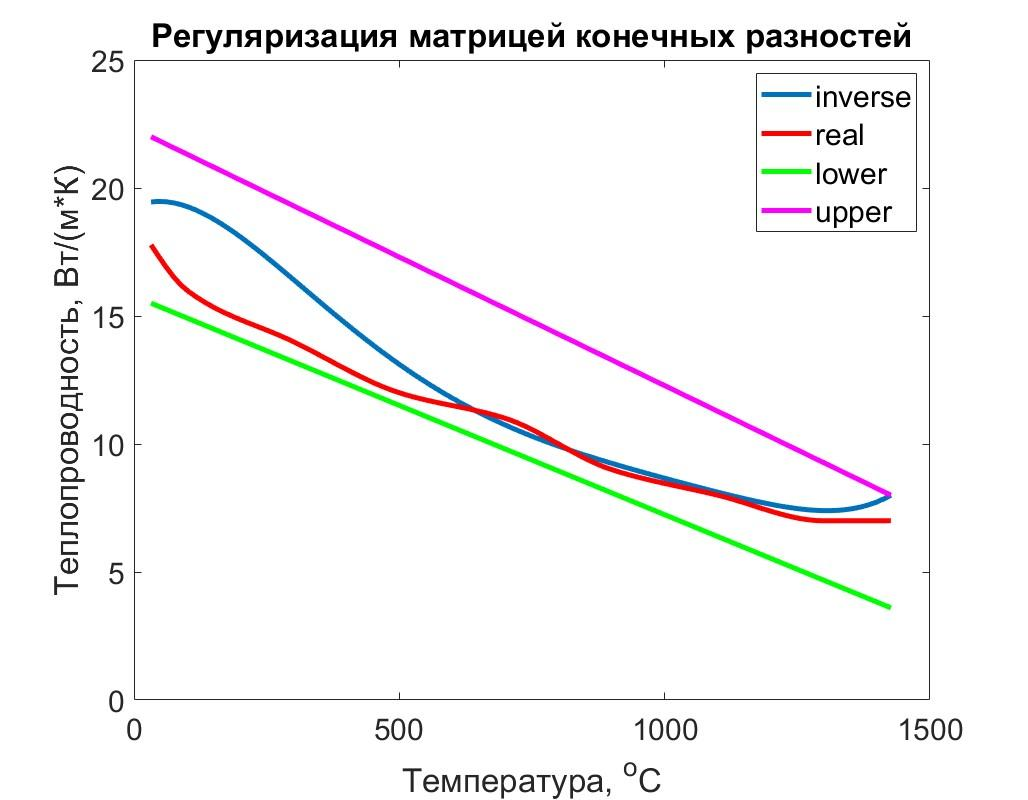

*Сравнение температурной зависимости теплопроводности восстановленной по экспериментальным данным с трех термопар с данным, полученными методом лазерной вспышки (слева обратная задача с регуляризацией единичной матрицей, справа - матричец конечных разностей). Температурная зависимость теплопроводности описывалась полиномами Бернштейна 8-й степени*